# ColorGrader - transform any video into a cinematic Almodóvar film

Takes in an RGB image/video, increases relative saturation for selected hues and desaturates remaining pixels. 

First generates test swatches to inspect how chosen parameters will transform images.

Generate function of hue-dependency by locating desired hues to stand out

Generate function of sat-dependency, hues to be made weaker are more dramatically weakened.

Can also boost chosen hues if required.

Copyright Joshua Harvey 2017

## Test swatches to find scaling factors

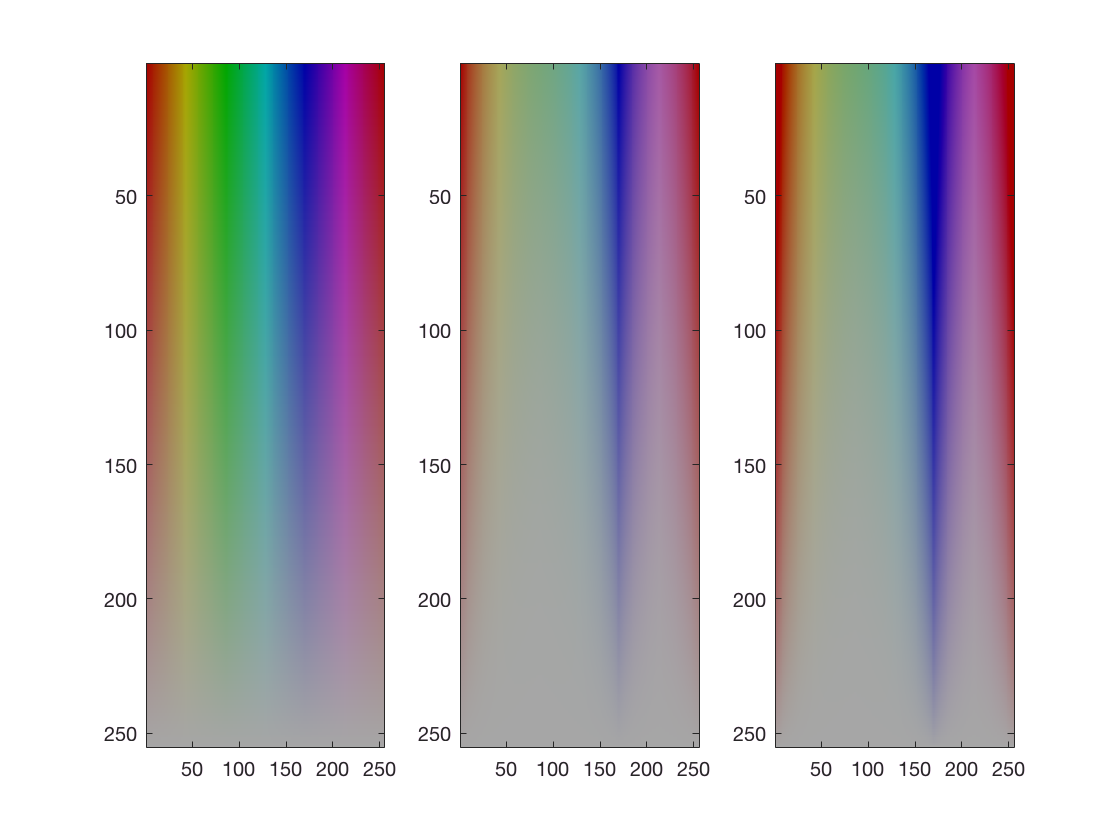

clear all

res = 255;

testh = repmat(linspace(0,1,res), [res 1]);
tests = repmat((linspace(1,0,res))', [1 res]);
testv = repmat(.65,res);

test(:,:,1) = testh;
test(:,:,2) = tests;
test(:,:,3) = testv;

rtest = uint8(hsv2rgb(test)*255);

uh = test(:,:,1);
us = test(:,:,2);
uv = test(:,:,3);

% specify hues to 'intensify' (H1, H2,... HN)
H1 = 0/255;
H2 = 170/255;
H = [H1 H2]; % H = [H1 H2... HN]
% make scaling matrix
q = 0.02; % intensifying factor for chosen hues (if wanting to actually boost selected hues)

for h = length(H):-1:1
    topdif = abs(uh-H(h));
    botdif = abs(uh-(H(h)+1));
    huedif = min(topdif,botdif);
    scales(:,:,h) = 1 + huedif*4;
end

for h = length(H):-1:1
    topdif = abs(uh-H(h));
    botdif = abs(uh-(H(h)+1));
    huedif = min(topdif,botdif) - q;
    qscales(:,:,h) = 1 + huedif*4;
end

scale = min(scales,[],3);
qscale = min(qscales,[],3);

rh = uh; % same hues
rs = us.^scale ./(scale.^1.5); % desaturate by scale
rq = us.^qscale ./(qscale.^1.5); % desaturate by scale
rv = uv; % same values

testR(:,:,1) = rh;
testR(:,:,2) = rs;
testR(:,:,3) = rv;
tested(:,:,:) = uint8(hsv2rgb(testR)*255);

testR(:,:,2) = rq;
qtested(:,:,:) = uint8(hsv2rgb(testR)*255);

figure;
h    = [];
h(1) = subplot(1,3,1);
h(2) = subplot(1,3,2);
h(3) = subplot(1,3,3);

image(rtest,'Parent',h(1));
image(tested,'Parent',h(2));
image(qtested,'Parent',h(3));

## Read in Video

vidn = '~/Downloads/MujerRetablos.mov'; % define pathname of original video
Video = VideoReader(vidn);
mov = double(read(Video))/255;
[a,b,c,t] = size(mov);

## Process Video

clearvars -except vidn Video mov a b c t

H1 = 0/255;
H2 = 175/255;
H = [H1 H2];
for k = t:-1:1
    
    imi = mov(:,:,:,k);
    % find pixels outside color band
    Himi = rgb2hsv(imi);
    uh = Himi(:,:,1);
    us = Himi(:,:,2);
    uv = Himi(:,:,3);
    
    
    % make scaling matrix
    
    q = 0; % intensifying factor for chosen hues eg 0.02
    for h = length(H):-1:1
        topdif = abs(uh-H(h));
        botdif = abs(uh-(H(h)+1));
        huedif = min(topdif,botdif);
        scales(:,:,h) = 1 + huedif*4;
    end
    
    scale = min(scales,[],3);
    
    rh = uh; % same hues
    rs = us.^scale ./(scale.^1.5); % desaturate by scale
    rv = uv; % same values
    
    R(:,:,1) = rh;
    R(:,:,2) = rs;
    R(:,:,3) = rv;
    r(:,:,:,k) = uint8(hsv2rgb(R)*255);
    
    if rem(k,20) == 0
        disp(k)
    end
end

    40



    20



## View and save video

implay(r)
newfilename = '~/Downloads/MujerRecolored.avi'; % specify new pathname for video
vidObj = VideoWriter(newfilename,'Uncompressed AVI'); 
open(vidObj);
writeVideo(vidObj,r);
close(vidObj)